clear;

cycles = ["us_ftp75","us_us06","eu_nedc","wltp_3b","cadc_urm150","cadc_urban","cadc_rural","cadc_mw150"];

d = [];
for n = cycles
    cycle = eval("elvio_cycle_"+n+"()");
    x = [0;cumsum(cycle(:,1))];
    v = [cycle(end,2);cycle(:,2)];
    a = ([cycle(:,2);cycle(1,2)]-[cycle(end,2);cycle(:,2)])./[cycle(:,1);1];
    T = x(end);

    vv = interp1(x,v,0.05:0.1:T);
    aa = interp1(x,a,0.05:0.1:T);

    mu = mean(vv);
    sd = std(vv);
    sk = skewness(vv);
    kt = kurtosis(vv);

    aabs = mean(abs(aa));
    asq  = mean(aa.^2);
    va   = mean(vv.*vv.*aa.*aa);
    pke  = mean(vv.*aa.*(0.5+0.5*sign(aa)));

    d = [d; T/60 mu sd sk kt aabs asq va pke];
end

d

d =    31.2833    9.4669    7.1247    0.3668    2.4893    0.4858    0.4549   25.0875    1.5443
   10.0000   21.4793   10.9487   -0.8339    2.2711    0.5943    0.9219  146.9375    4.0212
   18.3333   10.0105    8.5210    0.7208    2.8673    0.3098    0.2110   26.4875    0.9500
   30.0000   12.9257   10.0265    0.5909    2.4494    0.3535    0.2699   34.2833    1.9125
   52.4167   16.4348   12.0429    0.3274    1.9624    0.4041    0.3944   67.3680    2.5032
   16.5500    4.9043    4.7138    0.4939    1.8819    0.4933    0.5517   26.5753    1.3633
   18.0500   15.9487    6.8289   -0.3805    2.9373    0.3964    0.3658   64.0832    2.6332
   17.8167   27.6380   10.4665   -0.9804    2.9374    0.3289    0.2773  108.5882    3.4304


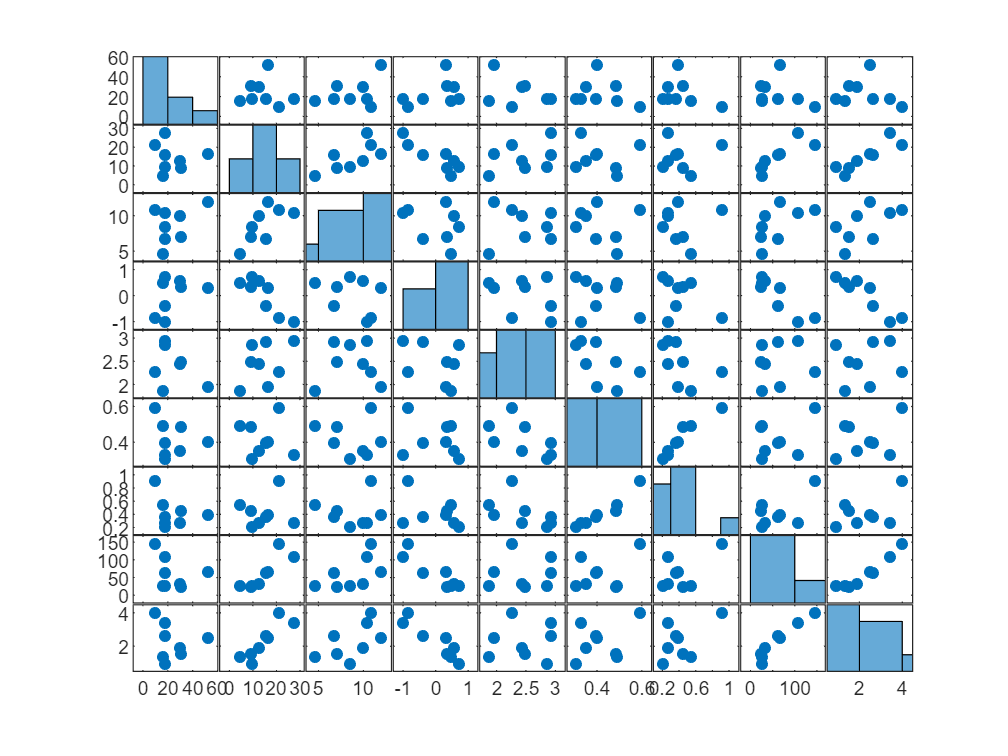

plotmatrix(d);